# Figures of average acoustic features per male bat in Acoustic Group 4

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home-1/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BoxPath = '/Users/elie/Box';
Path2Paper = fullfile(BoxPath, 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicAudioGood','CallType','OnSetOffsetSample',...
    'BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','F0_cv','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean', 'AmpPeriodF','AmpPeriodP')
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
MicAudioGoodInd = find(MicAudioGood01);
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;
fprintf(1,'In total, there are %d Vocal elements, %d are also of good microphone quality\n', length(MicAudioGood01), sum(MicAudioGood01))

In total, there are 36227 Vocal elements, 28091 are also of good microphone quality


Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
Path2RecordingTable = fullfile(BoxPath,'JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Female';
    end

end
USexDeaf = {'Kanamycin Male' 'Saline Male' 'Kanamycin Female' 'Saline Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

Construct the table of PAF for statistical purposes

Tbl =  table(BatID(MicAudioGoodInd(TmicAll4==4)),...
    CallType(MicAudioGoodInd(TmicAll4==4)),...
    Sex(MicAudioGoodInd(TmicAll4==4)),...
    Deaf(MicAudioGoodInd(TmicAll4==4)),...
    DurationElmt(MicAudioGoodInd(TmicAll4==4)),...
    RMS_mean(MicAudioGoodInd(TmicAll4==4)),...
    Sal_mean(MicAudioGoodInd(TmicAll4==4)),...
    F0_mean(MicAudioGoodInd(TmicAll4==4))/1000,...
    F0_cv(MicAudioGoodInd(TmicAll4==4)),...
    Spect_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    Spect_std(MicAudioGoodInd(TmicAll4==4))/10^3,...
    Spect_kurt(MicAudioGoodInd(TmicAll4==4)),...
    Spect_skew(MicAudioGoodInd(TmicAll4==4)),...
    Spect_ent(MicAudioGoodInd(TmicAll4==4)),...
    Time_mean(MicAudioGoodInd(TmicAll4==4)),...
    Time_std(MicAudioGoodInd(TmicAll4==4)),...
    Time_kurt(MicAudioGoodInd(TmicAll4==4)),...
    Time_skew(MicAudioGoodInd(TmicAll4==4)),...
    Time_ent(MicAudioGoodInd(TmicAll4==4)),...
    Q1_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    Q2_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    Q3_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    SpectMic_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    SpectMic_std(MicAudioGoodInd(TmicAll4==4))/10^3,...
    SpectMic_kurt(MicAudioGoodInd(TmicAll4==4)),...
    SpectMic_skew(MicAudioGoodInd(TmicAll4==4)),...
    SpectMic_ent(MicAudioGoodInd(TmicAll4==4)),...
    Q1Mic_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    Q2Mic_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    Q3Mic_mean(MicAudioGoodInd(TmicAll4==4))/10^3,...
    log(AmpPeriodF(MicAudioGoodInd(TmicAll4==4))),...
    AmpPeriodP(MicAudioGoodInd(TmicAll4==4)),...
    'VariableNames', {'BatID', 'CT','Sex','HorD',...
    'Duration (ms)','RMS mean','Saliency (AU)','Fund (kHz)','Fund CV','S mean (kHz)','S std (kHz)','S kurt (Hz)','S skew (Hz)','S ent',...
    'T mean (ms)','T std (ms)','T kurt (ms)','T skew (ms)','T ent','1st SQ (kHz)','2nd SQ (kHz)','3rd SQ (kHz)','Mic S mean (kHz)','Mic S std (kHz)',...
    'Mic S kurt (Hz)','Mic S skew (Hz)','Mic S ent','Mic 1st SQ (kHz)','Mic 2nd SQ (kHz)','Mic 3rd SQ (kHz)','Amp P F (log Hz)','Amp P P'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});

Go through all acoustic categories and calculate and plot the average values of features for all individuals

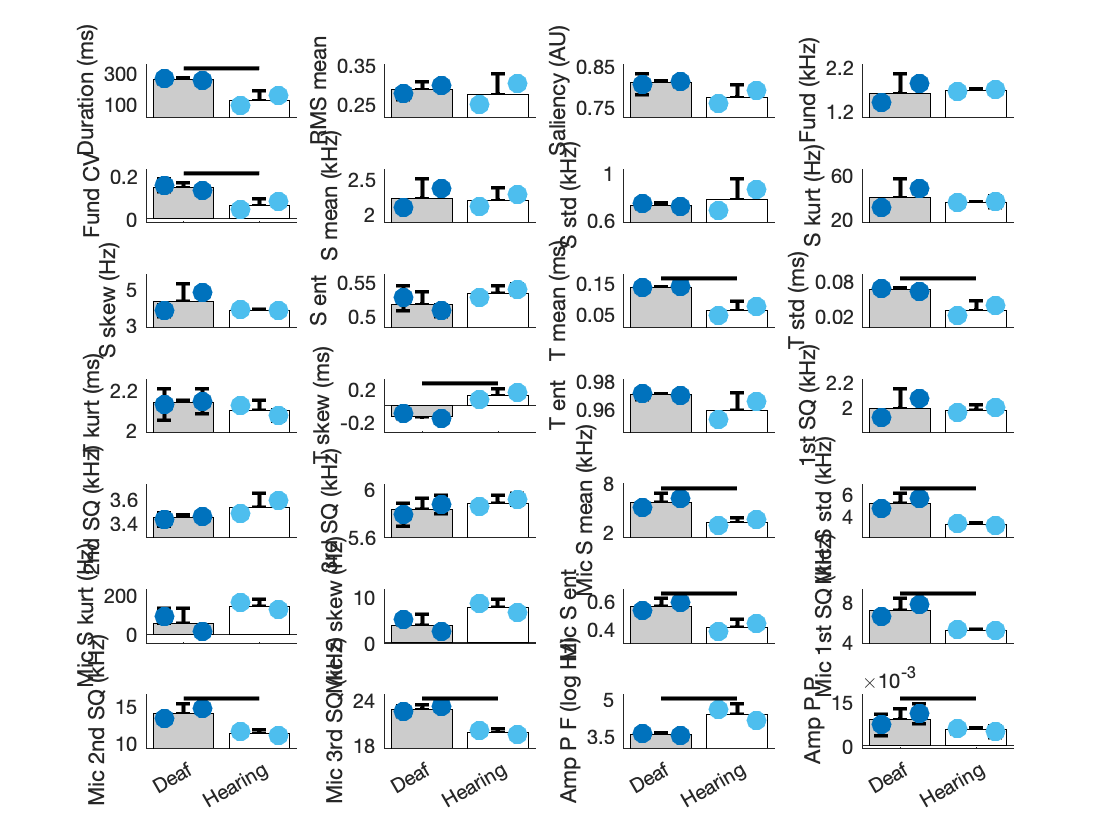

*********************     Calculations on Duration (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     3     39947    39965    -19970                                  
    lme      4     39940    39964    -19966    8.9648    1          0.0027523


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    39940    39964    -19966           39932   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        122.72      16.871    7.2741    3055    4.4106e-13     89.64     155.8
    {'HorD_D'     }        139.25      24.532    5.6762    3055    1.5058e-08    91.148    187.35

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     Upper 

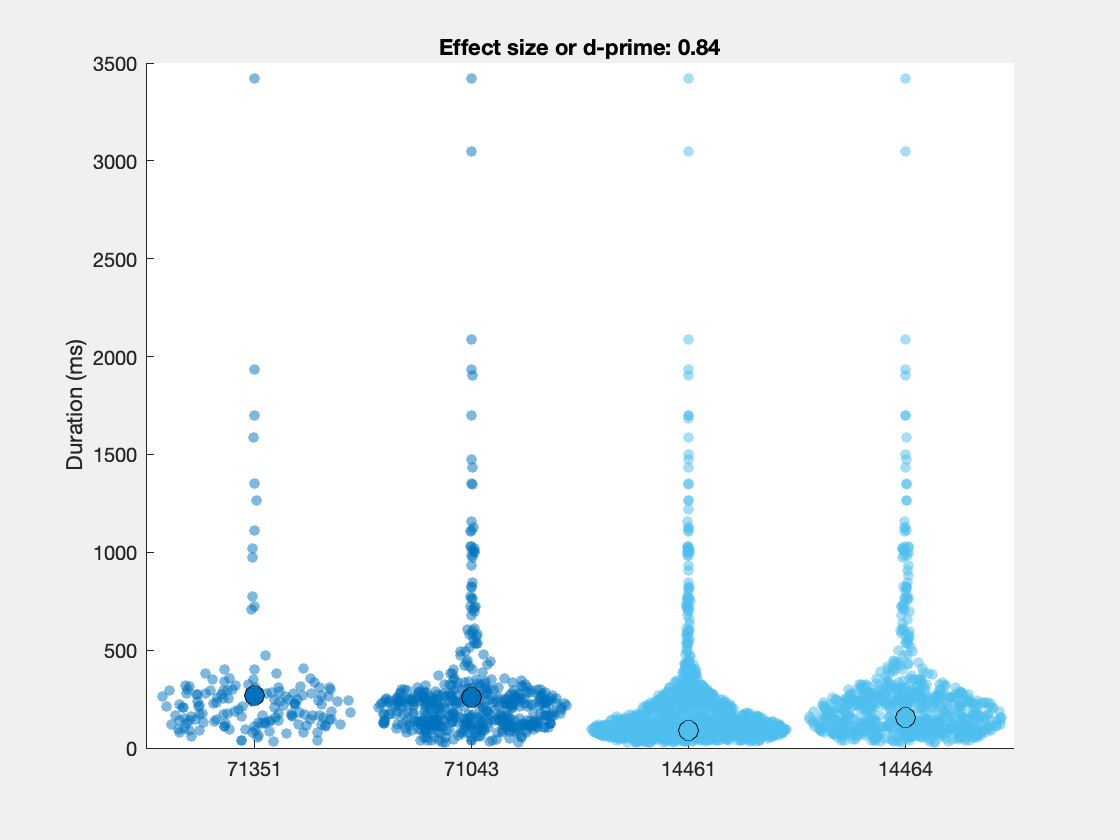

*********************     Calculations on RMS mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3       -5277    -5258.9    2641.5                                 
    lme      4     -5275.3    -5251.2    2641.6    0.30885    1          0.57838


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -5275.3    -5251.2    2641.6           -5283.3 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue        Lower        Upper   
    {'(Intercept)'}         0.27548    0.014253     19.328    3055    1.2904e-78      0.24754     0.30343
    {'HorD_D'     }        0.011633    0.020466    0.56841    3055        0.5698    -0.028495    0.051761

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type       

*********************     Calculations on Saliency (AU)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue
    lmeR     3     -3270.5    -3252.4    1638.3                                
    lme      4     -3259.1      -3235    1633.5    -9.4262    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3055
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC      LogLikelihood    Deviance
    -3259.1    -3235    1633.5           -3267.1 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}         0.77036    0.0029577    260.46    3053             0     0.76456     0.77616
    {'HorD_D'     }        0.039683    0.0059379    6.6831    3053    2.7705e-11    0.028041    0.051326

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on Fund (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     3     3771.3      3789    -1882.7                                 
    lme      4     3773.2    3796.8    -1882.6    0.10022    1          0.75157


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2659
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3773.2    3796.8    -1882.6          3765.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE         tStat       DF      pValue        Lower       Upper  
    {'(Intercept)'}             1.66    0.10762      15.424    2657    1.7929e-51       1.449      1.871
    {'HorD_D'     }        -0.048708    0.15315    -0.31804    2657       0.75048    -0.34901    0.25159

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on Fund CV   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -2358.4    -2340.7    1182.2                                  
    lme      4     -2364.7    -2341.2    1186.4    8.3417    1          0.0038745


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2659
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2364.7    -2341.2    1186.4           -2372.7 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}        0.059359    0.010824    5.4839    2657    4.5511e-08    0.038135    0.080584
    {'HorD_D'     }        0.083185    0.016149    5.1511    2657    2.7796e-07    0.051519     0.11485

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Es

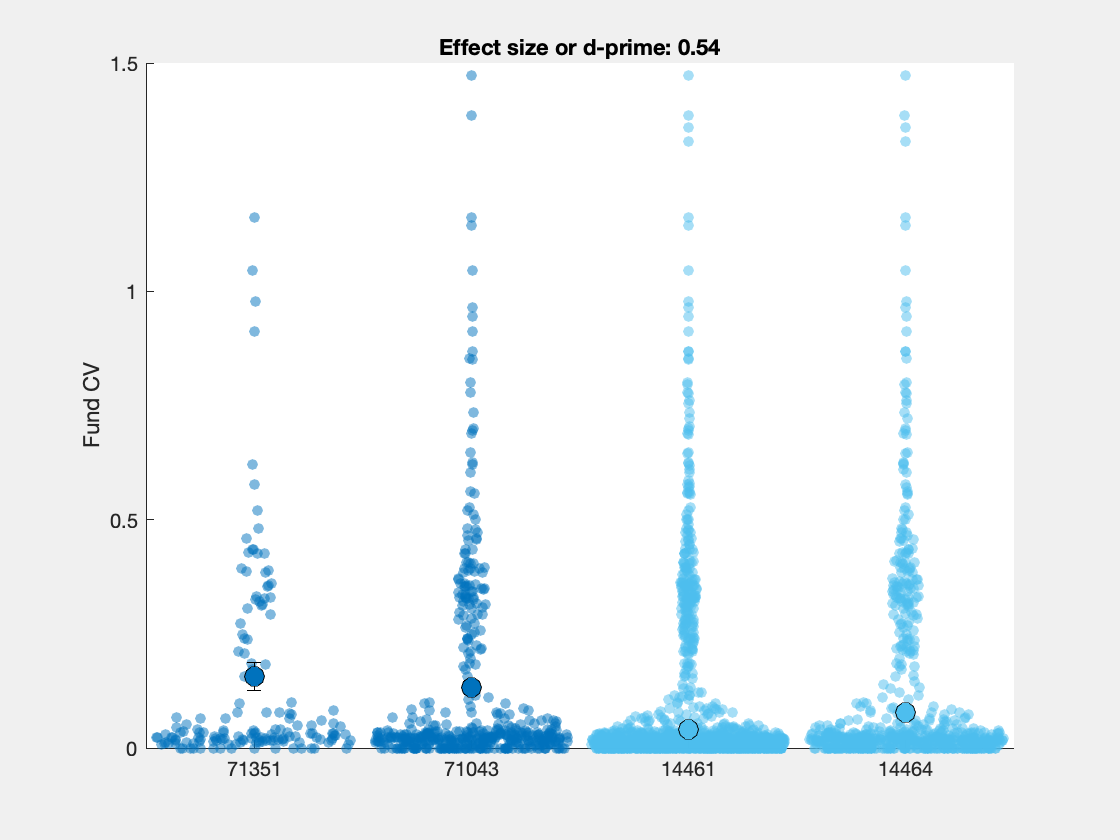

*********************     Calculations on S mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat      deltaDF    pValue 
    lmeR     3     561.25    579.33    -277.63                                  
    lme      4     563.18    587.28    -277.59    0.075516    1          0.78347


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    563.18    587.28    -277.59          555.18  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue         Lower       Upper  
    {'(Intercept)'}          2.1969    0.082202     26.726    3055    1.3787e-141      2.0358     2.3581
    {'HorD_D'     }        0.032226     0.11662    0.27633    3055        0.78231    -0.19644    0.26089

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on S std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     3      853.7    871.78    -423.85                                 
    lme      4     855.19    879.29     -423.6    0.51258    1          0.47402


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    855.19    879.29    -423.6           847.19  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF      pValue        Lower       Upper   
    {'(Intercept)'}          0.77353    0.045628      16.953    3055    1.1078e-61     0.68407       0.863
    {'HorD_D'     }        -0.048182     0.06525    -0.73843    3055       0.46031    -0.17612    0.079756

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type        

*********************     Calculations on S kurt (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lmeR     3     32904    32922    -16449                                
    lme      4     32910    32934    -16451    -3.4183    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    32910    32934    -16451           32902   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue         Lower     Upper 
    {'(Intercept)'}        35.528      1.0967    32.394    3055    3.7247e-198    33.377    37.678
    {'HorD_D'     }        8.1176      2.2025    3.6857    3055     0.00023205    3.7991    12.436

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate      Lower    Up

*********************     Calculations on S skew (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue
    lmeR     3     14471    14489    -7232.5                               
    lme      4     14479    14503    -7235.4    -5.938    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14479    14503    -7235.4          14471   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        3.8415      0.053815    71.385    3055             0     3.736    3.9471
    {'HorD_D'     }         0.708       0.10807    6.5512    3055    6.6748e-11    0.4961    0.9199

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower    U

*********************     Calculations on S ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -5249.6    -5231.5    2627.8                                 
    lme      4     -5248.3    -5224.2    2628.2    0.74702    1          0.38742


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -5248.3    -5224.2    2628.2           -5256.3 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat     DF      pValue        Lower        Upper   
    {'(Intercept)'}          0.53251    0.0021361    249.29    3055             0      0.52832      0.5367
    {'HorD_D'     }        -0.018901    0.0042898    -4.406    3055    1.0891e-05    -0.027312    -0.01049

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type    

*********************     Calculations on T mean (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -6620.2    -6602.1    3313.1                                  
    lme      4     -6628.5    -6604.4    3318.2    10.27     1          0.0013521


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6628.5    -6604.4    3318.2           -6636.5 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}        0.058294    0.0078311    7.4439    3055    1.2645e-13    0.042939    0.073649
    {'HorD_D'     }        0.077574     0.011424    6.7905    3055    1.3375e-11    0.055174    0.099973

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type          

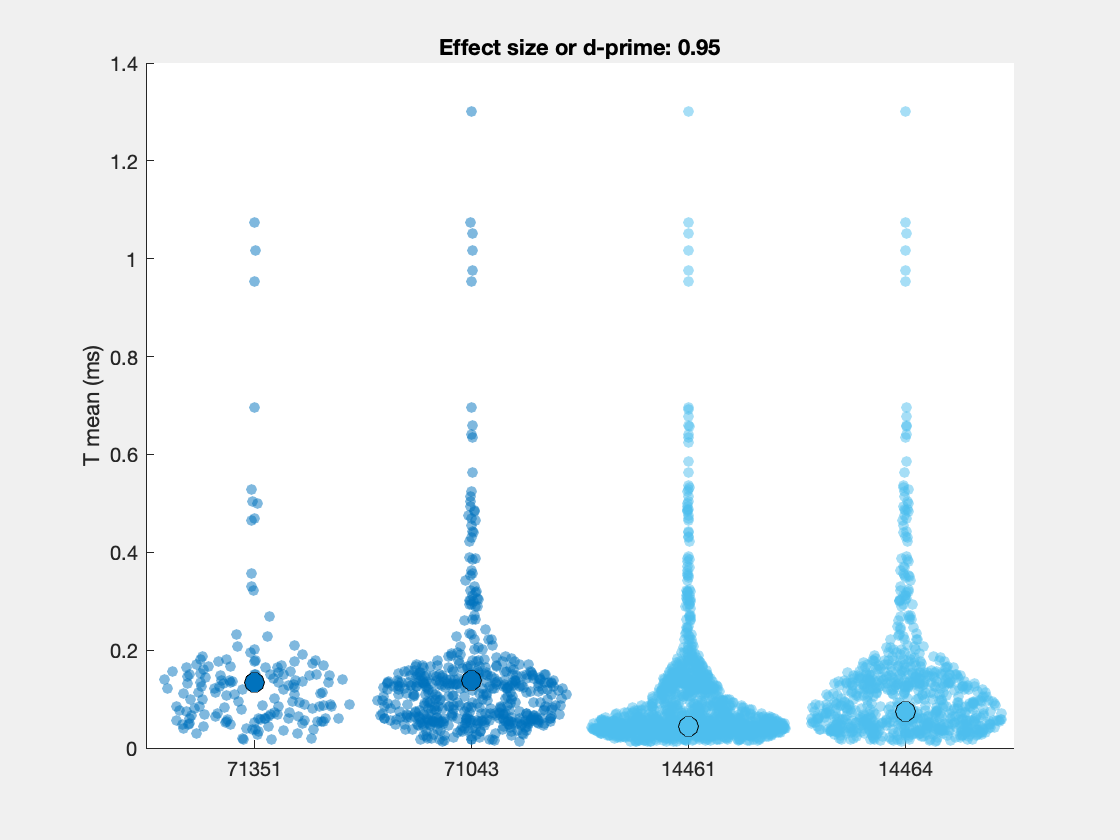

*********************     Calculations on T std (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -10223    -10204    5114.3                                  
    lme      4     -10229    -10205    5118.5    8.4325    1          0.0036858


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -10229    -10205    5118.5           -10237  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat    DF      pValue        Lower       Upper   
    {'(Intercept)'}        0.029306    0.0046085    6.359    3055    2.3332e-10    0.020269    0.038342
    {'HorD_D'     }        0.035302    0.0067013    5.268    3055    1.4747e-07    0.022163    0.048442

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

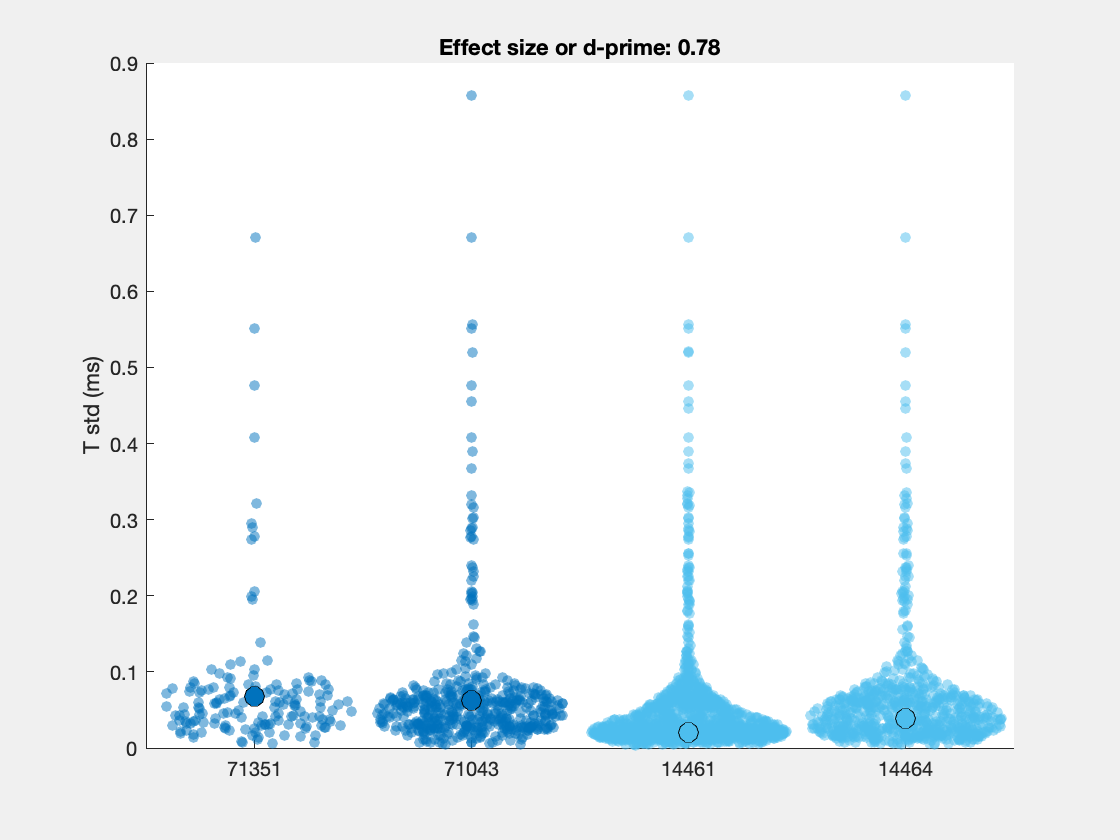

*********************     Calculations on T kurt (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     4545.8    4563.9    -2269.9                                
    lme      4     4545.2    4569.3    -2268.6    2.6301    1          0.10486


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    4545.2    4569.3    -2268.6          4537.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue     Lower         Upper   
    {'(Intercept)'}          2.1045    0.010599    198.55    3055          0        2.0837      2.1253
    {'HorD_D'     }        0.034528    0.021286    1.6221    3055    0.10489    -0.0072085    0.076264

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate 

*********************     Calculations on T skew (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     3     851.76    869.84    -422.88                                 
    lme      4      843.8     867.9     -417.9    9.9621    1          0.001598


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    843.8    867.9    -417.9           835.8   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue        Lower       Upper   
    {'(Intercept)'}         0.11932     0.02583     4.6194    3055     4.008e-06    0.068671     0.16996
    {'HorD_D'     }        -0.25006    0.037743    -6.6253    3055    4.0813e-11    -0.32406    -0.17605

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimat

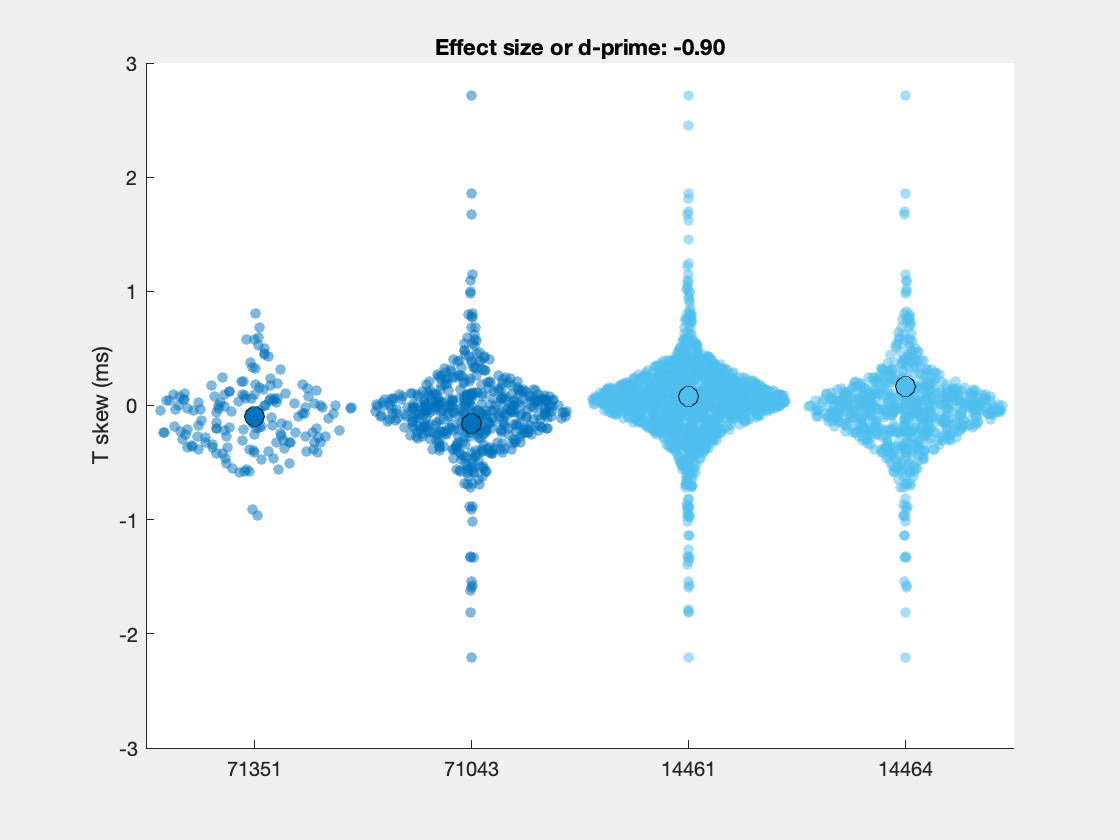

*********************     Calculations on T ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lmeR     3     -14594    -14576    7299.9                                 
    lme      4     -14596    -14571    7301.8    3.7012    1          0.054375


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -14596    -14571    7301.8           -14604  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue      Lower       Upper   
    {'(Intercept)'}         0.95881    0.0032498    295.03    3055           0     0.95244     0.96518
    {'HorD_D'     }        0.011427    0.0046603    2.4519    3055    0.014266    0.002289    0.020564

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate 

*********************     Calculations on 1st SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat      deltaDF    pValue 
    lmeR     3     -1867.1      -1849    936.56                                  
    lme      4     -1865.2    -1841.1    936.61    0.095429    1          0.75739


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -1865.2    -1841.1    936.61           -1873.2 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue     Lower        Upper 
    {'(Intercept)'}          1.9789    0.038462      51.45    3055          0       1.9035    2.0543
    {'HorD_D'     }        0.017051    0.054749    0.31145    3055    0.75548    -0.090298    0.1244

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate   

*********************     Calculations on 2nd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     3     2958.7    2976.7    -1476.3                                 
    lme      4     2957.9      2982      -1475    2.7602    1          0.096638


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    2957.9    2982    -1475            2949.9  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue     Lower      Upper    
    {'(Intercept)'}           3.5312    0.029205     120.91    3055          0     3.4739       3.5885
    {'HorD_D'     }        -0.083551    0.043375    -1.9262    3055    0.05417    -0.1686    0.0014974

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    L

*********************     Calculations on 3rd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue
    lmeR     3       6256    6274.1      -3125                                
    lme      4     6257.3    6281.4    -3124.7    0.71163    1          0.3989


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6257.3    6281.4    -3124.7          6249.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF      pValue     Lower        Upper   
    {'(Intercept)'}           5.8749    0.014025      418.89    3055          0       5.8474      5.9024
    {'HorD_D'     }        -0.023761    0.028165    -0.84363    3055    0.39894    -0.078986    0.031464

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on Mic S mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     12697    12715    -6345.5                                  
    lme      4     12691    12715    -6341.3    8.493     1          0.0035651


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12691    12715    -6341.3          12683   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        3.1836       0.3154    10.094    3055    1.3742e-23    2.5652     3.802
    {'HorD_D'     }        2.4739      0.45107    5.4844    3055    4.4863e-08    1.5894    3.3583

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower      Up

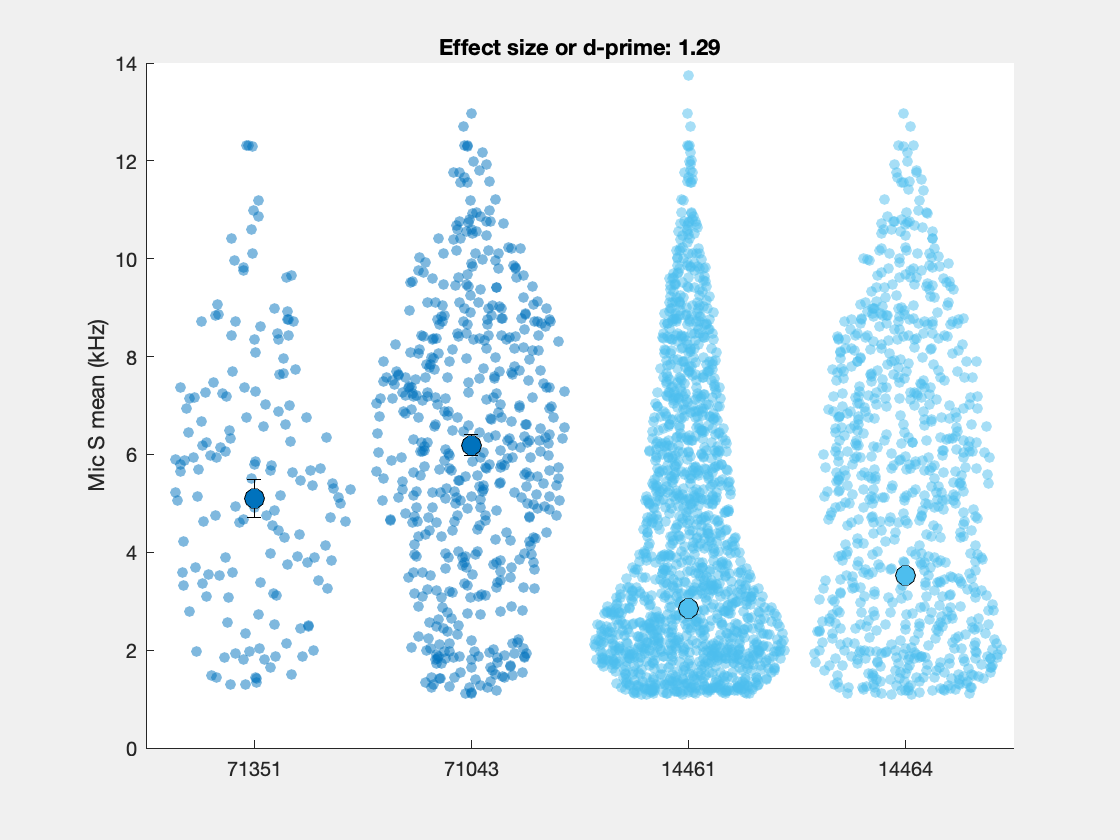

*********************     Calculations on Mic S std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     3     12086    12104    -6039.9                                 
    lme      4     12078    12102    -6035.2    9.3974    1          0.002173


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12078    12102    -6035.2          12070   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        3.2115      0.21279    15.092    3055      1.08e-49    2.7943    3.6287
    {'HorD_D'     }        1.9448      0.30691    6.3365    3055    2.6964e-10     1.343    2.5465

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower      Up

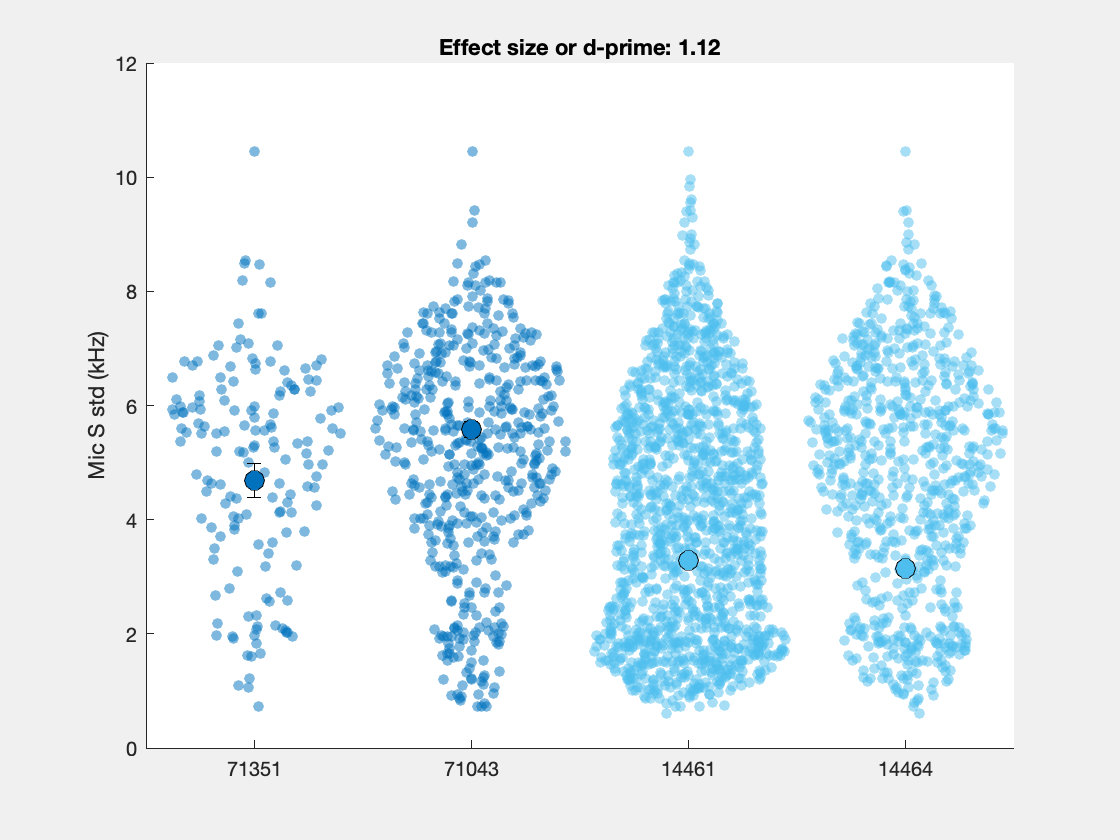

*********************     Calculations on Mic S kurt (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     3     42057    42075    -21026                                 
    lme      4     42054    42079    -21023    4.9304    1          0.026389


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    42054    42079    -21023           42046   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF      pValue        Lower     Upper  
    {'(Intercept)'}         143.79     19.044     7.5506    3055    5.6876e-14    106.45     181.13
    {'HorD_D'     }        -92.531     28.088    -3.2943    3055    0.00099798    -147.6    -37.457

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower    U

*********************     Calculations on Mic S skew (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lmeR     3     19802    19820    -9897.9                                
    lme      4     19798    19822    -9895.1    5.7319    1          0.01666


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    19798    19822    -9895.1          19790   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'}         7.6935     0.76421     10.067    3055    1.7841e-23     6.1951     9.1919
    {'HorD_D'     }        -4.0045      1.1016    -3.6352    3055    0.00028233    -6.1645    -1.8446

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lowe

*********************     Calculations on Mic S ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -4124.6    -4106.5    2065.3                                  
    lme      4       -4131    -4106.9    2069.5    8.4238    1          0.0037034


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC        LogLikelihood    Deviance
    -4131    -4106.9    2069.5           -4139   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower       Upper  
    {'(Intercept)'}        0.41183     0.019234    21.411    3055    7.0646e-95     0.37412    0.44955
    {'HorD_D'     }        0.14876     0.027536    5.4023    3055     7.085e-08    0.094768    0.20275

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate 

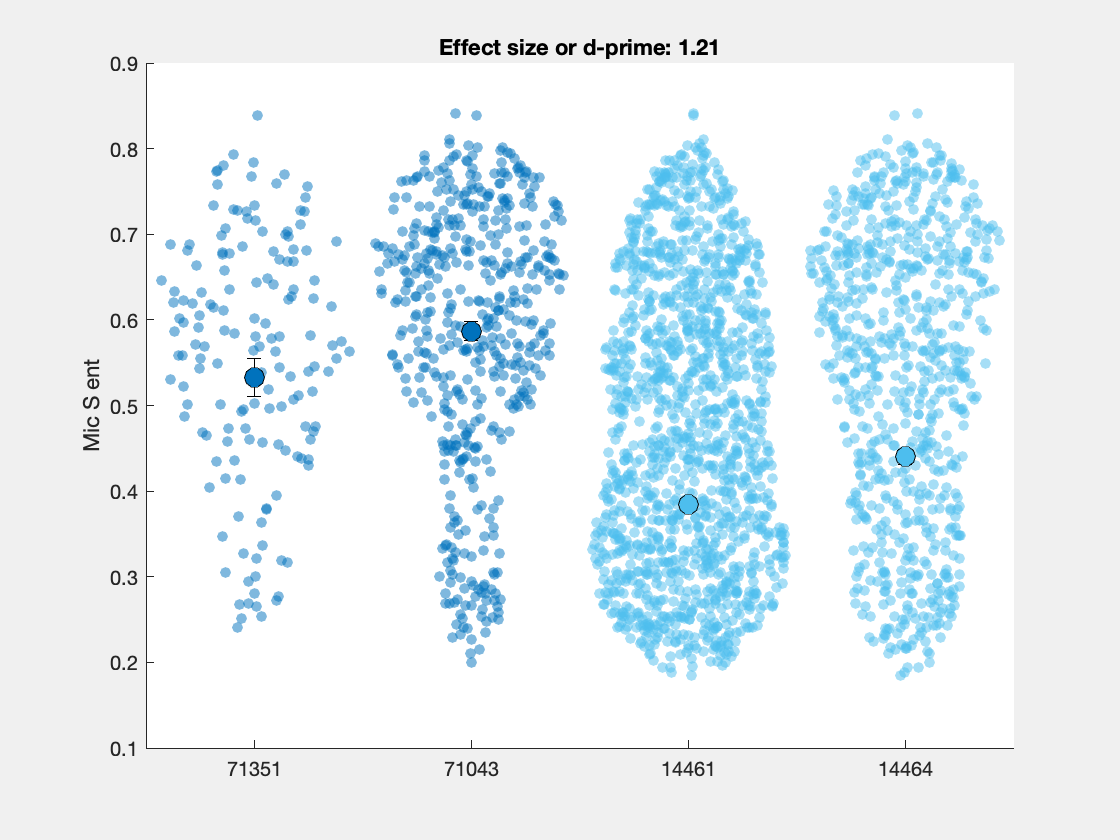

*********************     Calculations on Mic 1st SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     12363    12381    -6178.3                                  
    lme      4     12357    12381    -6174.4    7.8039    1          0.0052134


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12357    12381    -6174.4          12349   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        5.1406      0.28337    18.141    3055    6.2385e-70     4.585    5.6962
    {'HorD_D'     }         2.032      0.40574    5.0081    3055    5.8089e-07    1.2364    2.8275

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower      Up

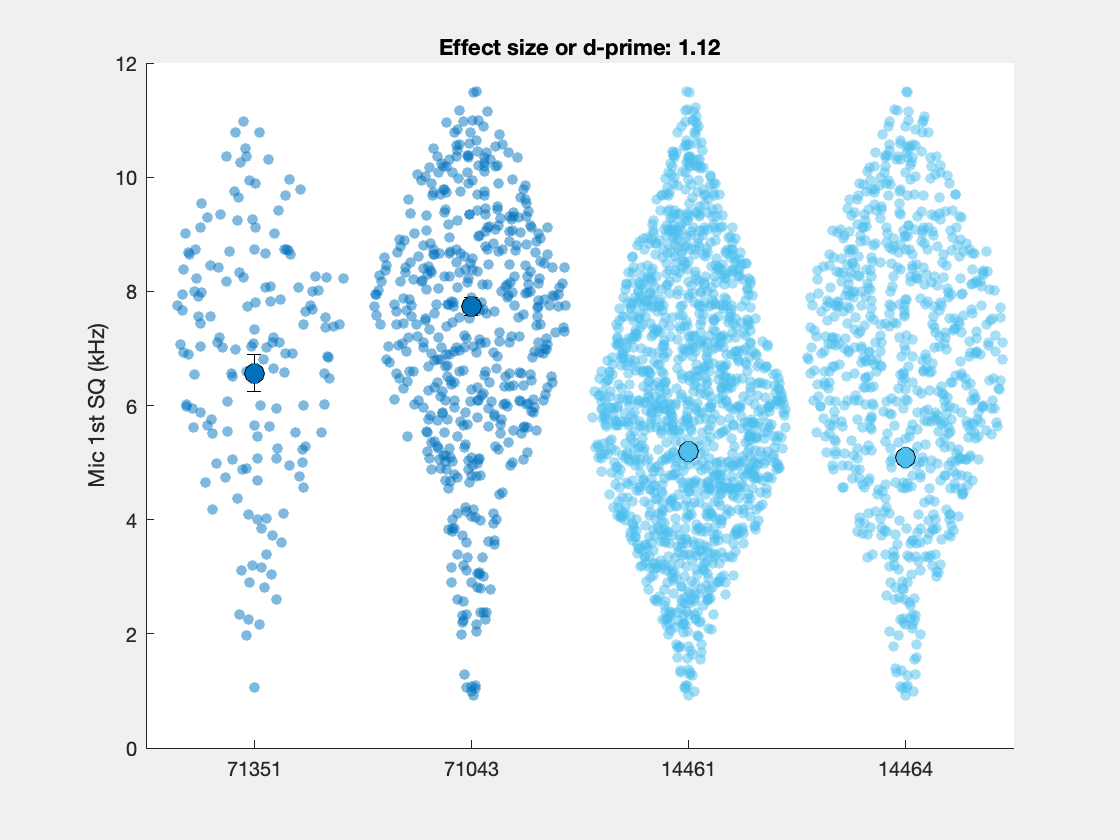

*********************     Calculations on Mic 2nd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     15713    15731    -7853.5                                  
    lme      4     15706    15731    -7849.2    8.4747    1          0.0036012


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    15706    15731    -7849.2          15698   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower     Upper 
    {'(Intercept)'}        11.259      0.33933    33.181    3055    1.9138e-206    10.594    11.925
    {'HorD_D'     }        2.7412      0.49204    5.5711    3055     2.7514e-08    1.7764     3.706

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     

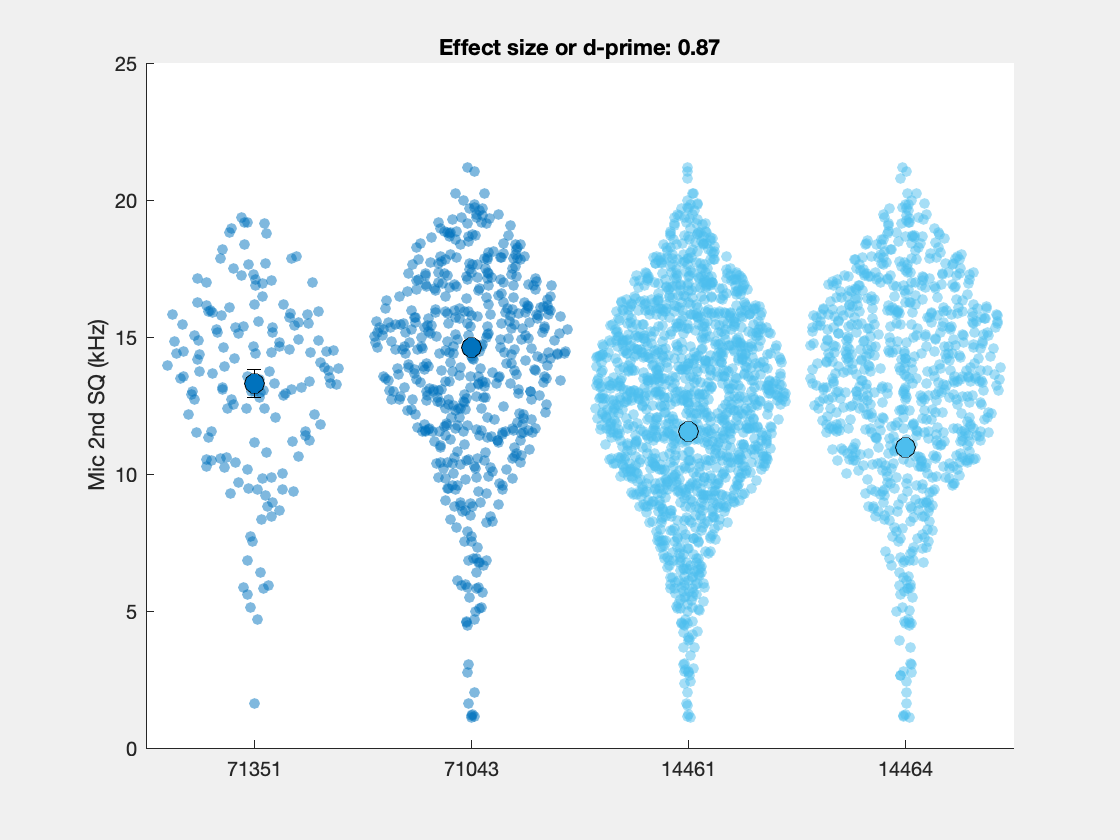

*********************     Calculations on Mic 3rd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue    
    lmeR     3     18877    18895    -9435.7                                   
    lme      4     18867    18891    -9429.4    12.681    1          0.00036942


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    18867    18891    -9429.4          18859   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        19.742       0.1103    178.98    3055             0    19.526    19.958
    {'HorD_D'     }        3.2287      0.22151    14.576    3055    1.4138e-46    2.7944     3.663

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate      Lower    Up

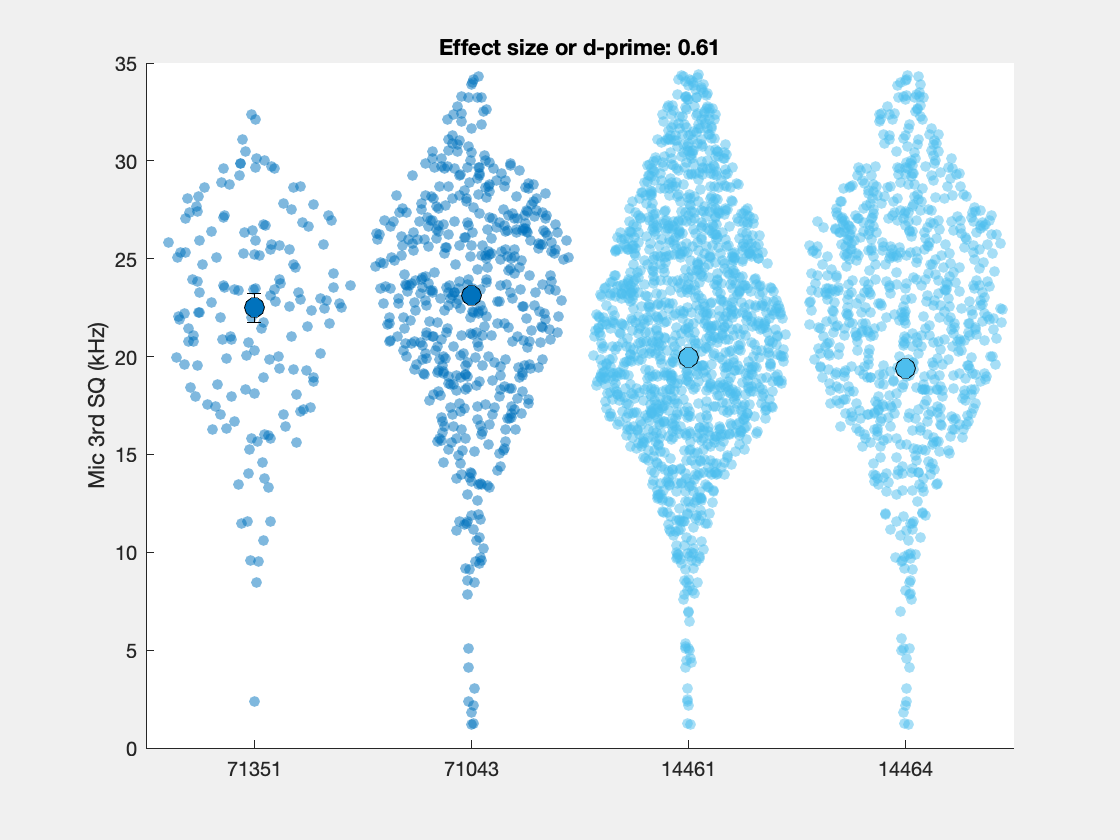

*********************     Calculations on Amp P F (log Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue   
    lmeR     3     6037.1    6055.2    -3015.6                                  
    lme      4     6031.3    6055.4    -3011.7    7.8186    1          0.0051711


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3025
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6031.3    6055.4    -3011.7          6023.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue         Lower      Upper   
    {'(Intercept)'}          4.3564    0.11436     38.092    3023    1.1365e-259     4.1322      4.5807
    {'HorD_D'     }        -0.79999    0.16334    -4.8977    3023     1.0207e-06    -1.1203    -0.47972

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

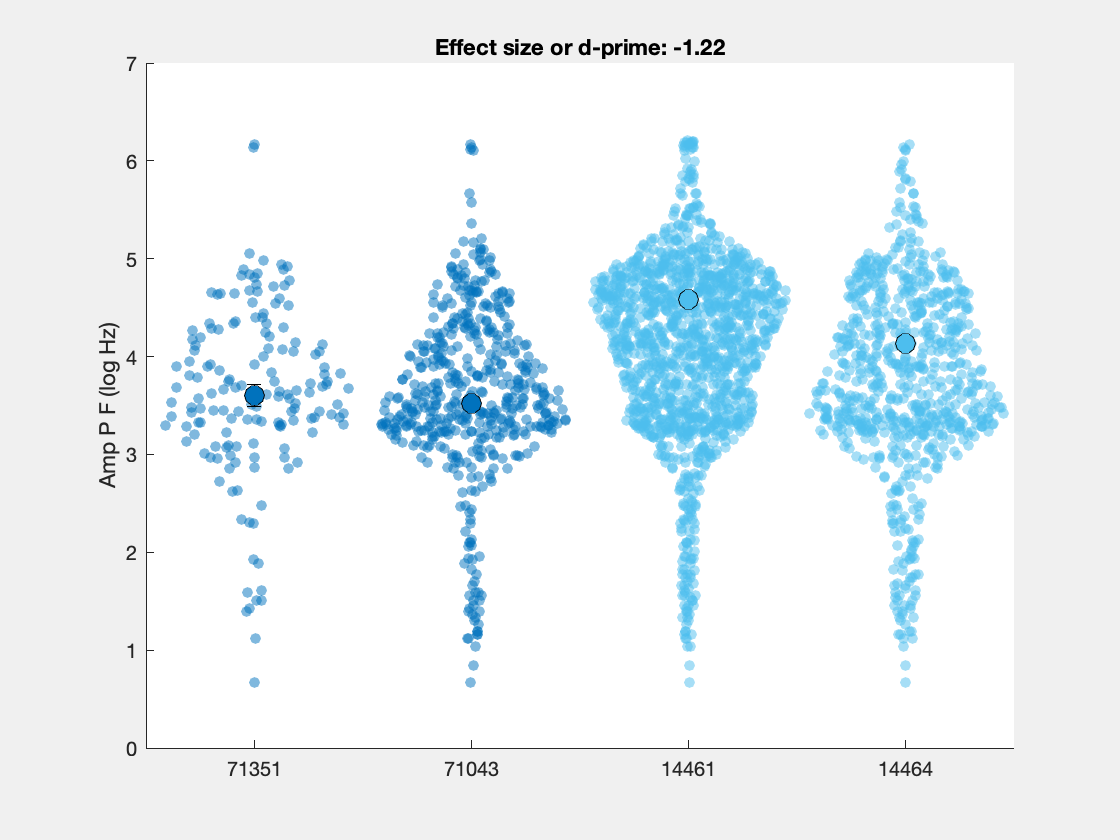

*********************     Calculations on Amp P P   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -12177    -12159    6091.5                                  
    lme      4     -12185    -12161    6096.6    10.106    1          0.0014781


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3057
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -12185    -12161    6096.6           -12193  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE            tStat     DF      pValue        Lower        Upper    
    {'(Intercept)'}        0.0054943    0.00068688    7.9988    3055    1.7658e-15    0.0041475    0.0068411
    {'HorD_D'     }        0.0043887     0.0013794    3.1816    3055     0.0014794     0.001684    0.0070934

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type  

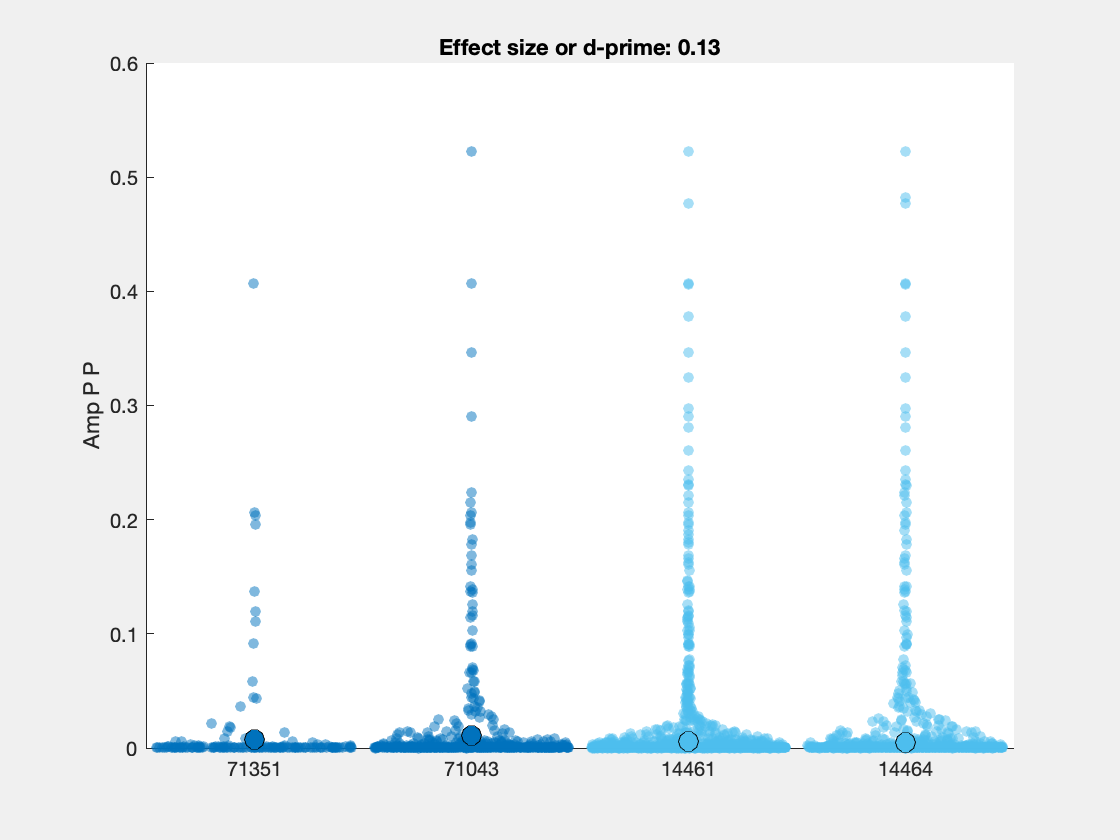

% List of variables
AcVars = Tbl.Properties.VariableNames(5:end);
Pvalue_matrix_LME = nan(length(AcVars),1);
Effect_size = nan(length(AcVars),1);
BatMales = BatName(contains(BatSexDeaf, 'Male'));
BatSexDeafMales = BatSexDeaf(contains(BatSexDeaf, 'Male'));
AcVar_mean_pBat = nan(length(AcVars), size(BatMales,2));
AcVar_se_pBat = nan(length(AcVars), size(BatMales,2));
AcVar_std_pBat = nan(length(AcVars), size(BatMales,2));
N_pBat = nan(length(AcVars), size(BatMales,2));
Col_pBat = cell(length(AcVars),1);
AcVarMean_HD = nan(length(AcVars),2);
AcVarSE_HD = nan(length(AcVars),2);

Fig1=figure(1);
clf
T=tiledlayout(7,4,'TileSpacing','compact');
set(gcf,'Visible','on')
INN = contains(Tbl.Sex, 'M');
for vv=1:length(AcVars)
    fprintf(1, '*********************     Calculations on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    Tbl_local = table(Tbl.BatID(INN), Tbl.CT(INN), Tbl.HorD(INN), AcVar(INN), 'VariableNames', {'BatID', 'CT','HorD', 'AcVar'});
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    Tbl_local.AcVar(isinf(Tbl_local.AcVar)) = nan;

    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ 1 + (1|BatID)');
    TestLME_HD=compare(lmeR, lme)
    Pvalue_matrix_LME(vv) = TestLME_HD.pValue(2);

    lme

    % Nice plot 1
    Col_pBat{vv} = nan(length(BatMales),3);
    for bb=1:length(BatMales)
        Ind = strcmp(Tbl_local.BatID,num2str(BatMales(bb)));
        
        AcVar_mean_pBat(vv,bb) = mean(Tbl_local.AcVar(Ind), 'omitnan');
        AcVar_se_pBat(vv,bb) = std(Tbl_local.AcVar(Ind), 'omitnan')/sum(~isnan(Tbl_local.AcVar(Ind)))^0.5;
        AcVar_std_pBat(vv,bb) = std(Tbl_local.AcVar(Ind), 'omitnan');
        N_pBat(vv,bb) = sum(~isnan(Tbl_local.AcVar(Ind)));
        Col_pBat{vv}(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeafMales{bb}),:);
    end

   
    AcVarMean_HD(vv,:) = [mean(AcVar_mean_pBat(vv,contains(BatSexDeafMales, 'Kanamycin'))) mean(AcVar_mean_pBat(vv,contains(BatSexDeafMales, 'Saline')))];
    AcVarSE_HD(vv,:) = [std(AcVar_mean_pBat(vv,contains(BatSexDeafMales, 'Kanamycin')))/sum(contains(BatSexDeafMales, 'Kanamycin'))^0.5 std(AcVar_mean_pBat(vv,contains(BatSexDeafMales, 'Saline')))/sum(contains(BatSexDeafMales, 'Saline'))^0.5];
    
    figure(1)
    N=nexttile(vv,[1,1]);
    XHorD = [0.5 1.5 2.5 3.5];
%     XHorD(contains(BatSexDeafMales, 'Saline')) = XHorD(contains(BatSexDeafMales, 'Saline'))+2;
    errorbar([1 3],AcVarMean_HD(vv,:), zeros(1,length(AcVarSE_HD(vv,:))), 2*AcVarSE_HD(vv,:), 'k.','LineWidth',2)
    hold on
    B=bar([1 3], AcVarMean_HD(vv,:));
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 'k.','LineWidth',2)
    hold on
    scatter(XHorD,AcVar_mean_pBat(vv,:),100, Col_pBat{vv}, 'filled')
    ylabel(sprintf('%s', AcVars{vv}), 'FontSize',12)
    XLim = [0 4];
    set(gca, 'XLim', XLim);
    YLim = get(gca, 'YLim');
    MinVal = min(AcVar_mean_pBat(vv,:)-2*AcVar_se_pBat(vv,:));
    MaxVal = max([AcVar_mean_pBat(vv,:)+2*AcVar_se_pBat(vv,:) AcVarMean_HD(vv,:) + 2*AcVarSE_HD(vv,:)]);
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
%     YLim(1) = MinVal - (MaxVal-MinVal)*2/3;
    set(gca, 'YLim', YLim)
%     if vv==length(AcVars)
%         for ct=1:length(USexDeaf(1:2))
%             text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
%         end
%     end
    if vv>24
        set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'}, 'FontSize',12)
    else
        set(gca, 'XTick', [1 3],'XTickLabel', {'' ''})
    end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)], 'FontSize',10)
    hold off
    if ~(TestLME_HD.pValue(2) <0.01)
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
%         T.FontWeight = 'normal';
%         T.Color = 0.7.*ones(1,3);
    else
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        hold on
        plot([1 3], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
%         text(2,(19/20*diff(YLim) + YLim(1)), '<.01','FontSize', 9)
    end
    N.Box = 0;
    

    %         nexttile
    %         errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
    %         hold on
    %         scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
    %         ylabel(sprintf('%s (z-scored)', AcVars{vv}))
    %         XLim = [0 4];
    %         set(gca, 'XLim', XLim);
    %         YLim = get(gca, 'YLim');
    %         for ct=1:length(USexDeaf)
    %             text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
    %         end
    %         set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
    %         hold off
    %         title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))
    if Pvalue_matrix_LME(vv)<0.01
        Effect_size(vv) = lme.Coefficients.Estimate(2)/(sum((AcVar_std_pBat(vv,:).^2).*N_pBat(vv,:))./sum(N_pBat(vv,:)))^0.5;
        figure()
        set(gcf,'Visible','on')
        % Nice plot per bat
        
        for bb=1:length(BatMales)
            Ind = INN(strcmp(Tbl.BatID(INN),num2str(BatMales(bb))));
            hold on
            swarmchart(bb*ones(sum(Ind),1),AcVar(Ind),30,Col_pBat{vv}(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
        end
    
        hold on
        errorbar(1:4,AcVar_mean_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 'k.')
        hold on
        scatter(1:4,AcVar_mean_pBat(vv,:),100, Col_pBat{vv}, 'filled', 'MarkerEdgeColor', 'k')
        ylabel(sprintf('%s', AcVars{vv}));
        set(gca, 'XTick', 1:4,'XTickLabel', BatMales)
        hold off
        title(sprintf('Effect size or d-prime: %.2f', Effect_size(vv)))
    end

end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

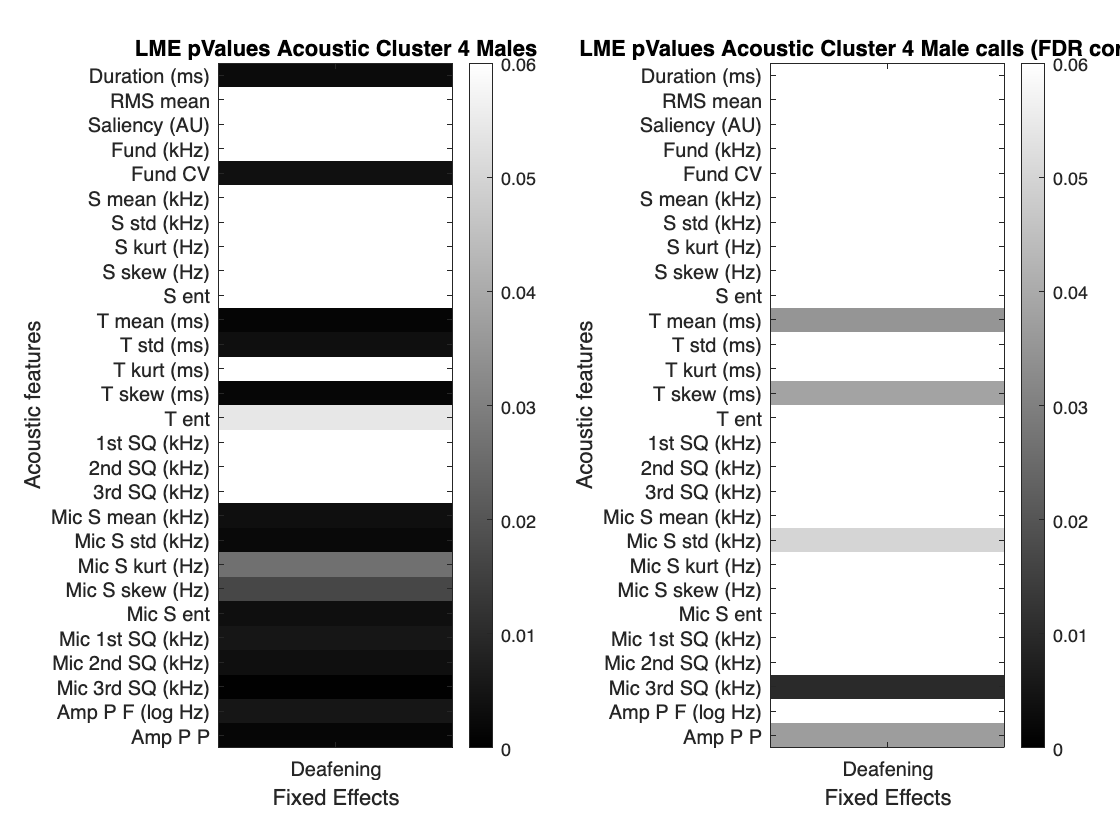

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank)) within each acoustic cluster
NVars = size(Pvalue_matrix_LME,1);

Pvalue_vector = Pvalue_matrix_LME;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrix_LME_FDR = Pvalue_vectorFDR;

figure()
tiledlayout(1,2)
nexttile
Im = imagesc(Pvalue_matrix_LME);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 4 Males')
nexttile
Im = imagesc(Pvalue_matrix_LME_FDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 4 Male calls (FDR corrected)')

Pvalue_matrix_LME

Pvalue_matrix_LME =     0.0028
    0.5784
    1.0000
    0.7516
    0.0039
    0.7835
    0.4740
    1.0000
    1.0000
    0.3874


PV_sig = Pvalue_matrix_LME(Pvalue_matrix_LME<0.01);
PV_postHoc_sig = Pvalue_matrix_LME_FDR(Pvalue_matrix_LME<0.01);
AcVarsSig = AcVars(Pvalue_matrix_LME<0.01);
for vv=1:length(AcVarsSig)
    fprintf(1,'%s %.4f  %.4f\n',AcVarsSig{vv},PV_sig(vv), PV_postHoc_sig(vv))
end

Duration (ms) 0.0028  0.0606
Fund CV 0.0039  0.0659
T mean (ms) 0.0014  0.0352
T std (ms) 0.0037  0.0700
T skew (ms) 0.0016  0.0384
Mic S mean (kHz) 0.0036  0.0749
Mic S std (kHz) 0.0022  0.0500
Mic S ent 0.0037  0.0667
Mic 1st SQ (kHz) 0.0052  0.0782
Mic 2nd SQ (kHz) 0.0036  0.0720
Mic 3rd SQ (kHz) 0.0004  0.0100
Amp P F (log Hz) 0.0052  0.0827
Amp P P 0.0015  0.0370


for vv=1:length(AcVars)
    if Pvalue_matrix_LME_FDR(vv)<0.01
        fprintf(1,'** %s %.4f %.4f **\n',AcVars{vv},Pvalue_matrix_LME(vv),Pvalue_matrix_LME_FDR(vv))
    elseif Pvalue_matrix_LME(vv)<0.01
        fprintf(1,'* %s %.4f %.4f *\n',AcVars{vv},Pvalue_matrix_LME(vv),Pvalue_matrix_LME_FDR(vv))
    else
        fprintf(1,'%s %.4f %.4f\n',AcVars{vv},Pvalue_matrix_LME(vv),Pvalue_matrix_LME_FDR(vv))
    end
end

* Duration (ms) 0.0028 0.0606 *


RMS mean 0.5784 3.4703
Saliency (AU) 1.0000 2.0000
Fund (kHz) 0.7516 3.7579


* Fund CV 0.0039 0.0659 *


S mean (kHz) 0.7835 2.3504
S std (kHz) 0.4740 3.3182
S kurt (Hz) 1.0000 1.0000
S skew (Hz) 1.0000 1.0000
S ent 0.3874 3.4868


* T mean (ms) 0.0014 0.0352 *
* T std (ms) 0.0037 0.0700 *


T kurt (ms) 0.1049 1.0486


* T skew (ms) 0.0016 0.0384 *


T ent 0.0544 0.6525
1st SQ (kHz) 0.7574 3.0295
2nd SQ (kHz) 0.0966 1.0630
3rd SQ (kHz) 0.3989 3.1912


* Mic S mean (kHz) 0.0036 0.0749 *
* Mic S std (kHz) 0.0022 0.0500 *


Mic S kurt (Hz) 0.0264 0.3431
Mic S skew (Hz) 0.0167 0.2332


* Mic S ent 0.0037 0.0667 *
* Mic 1st SQ (kHz) 0.0052 0.0782 *
* Mic 2nd SQ (kHz) 0.0036 0.0720 *


** Mic 3rd SQ (kHz) 0.0004 0.0100 **


* Amp P F (log Hz) 0.0052 0.0827 *
* Amp P P 0.0015 0.0370 *


Add the p-avlues after FDR correcion to the figure

for vv=1:length(AcVars)
    YLabel = Fig1.Children.Children(vv).YLabel.String;
    IndAcVars = contains(AcVars,YLabel);
    if sum(IndAcVars>1)
        keyboard % we should not end up here
    end
    if Pvalue_matrix_LME(IndAcVars)<0.01
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        YLim = Fig1.Children.Children(vv).YLim;
        hold on
        text(Fig1.Children.Children(vv),1.25,(diff(YLim) + YLim(1)), sprintf('p=%.3f', Pvalue_matrix_LME_FDR(IndAcVars)),'FontSize', 9)
    end
end

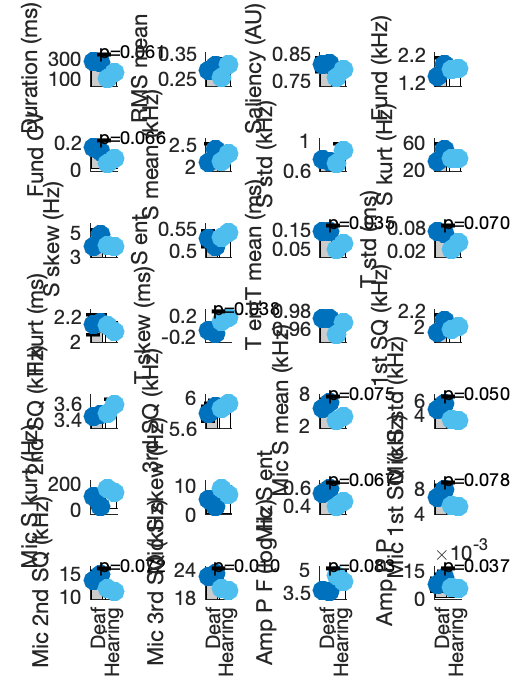

Fig1.Units = 'centimeters';
Fig1.Position(3:4) = [9 12];
Fig1.PaperSize = [9 12];
save(fullfile(LocalDataDir, "Data4_SupFigue2_PAF_MalesAcGroup4_Calls"), 'AcVar_mean_pBat','AcVar_se_pBat','Col_pBat', 'AcVarMean_HD', 'AcVarSE_HD', 'BatSexDeafMales', 'AcVars', 'USexDeaf', 'AcVar_std_pBat' ,'N_pBat', 'Pvalue_matrix_LME', 'Pvalue_matrix_LME_FDR', 'Effect_size');
print(Fig1,fullfile(Path2Paper,'SupFigure14_PAF_MalesAcGroup4.pdf'),'-dpdf','-fillpage')